# EB3100 Praktikum Teknik Biomedis 2

# Tugas 4 Estimasi HR dan SpO2

Spesifikasi Alat:

- Fs = 100 sps

- Nilai = 30.000 - 50.000

- Resolusi HR = 1 bpm

- Resolusi SpO2 = 1%

- Rentang HR = 25 - 250 bpm

- Rentang SpO2 = 0 - 100%

- Akurasi HR = +- 1% atau +- 1 bpm

- Akurasi SpO2 = +- 2% @70-100%

            *nomor 3-8 berdasarkan Yuwell Finger Pulse Oximeter YX102

Spesifikasi Filter

        1. Passband = 0.41667 - 4.16667 Hz

                Berdasarkan rentang heart rate (nomor 5), dapat dihitung frekuensi yaitu

                
$$f_1 =\frac{25\;\textrm{bpm}}{60}=0\ldotp 41667\;\textrm{Hz}$$


                
$$f_2 =\frac{250\;\textrm{bpm}}{60}=4\ldotp 16667\;\textrm{Hz}$$


        2. Resolusi frekuensi = 0.01667 Hz

                Berdasarkan resolusi heart rate (nomor 3), dapat dihitung frekuensi yaitu

                
$$f_r =\frac{1\;\textrm{bpm}}{60}=0\ldotp 01667\;\textrm{Hz}$$


        3. Panjang sampel = 8192 sampel

                Berdasarkan resolusi frekuensi dan sampling rate (nomor 1), dapat dihitung panjang sampel yang dibutuhkan

                
$$N=\frac{F_{s\;} }{f_r }=\frac{100\;\textrm{sps}}{0\ldotp 01667\;\textrm{Hz}}=6000\;\textrm{sampel}$$


                Dibulatkan ke 2 pangkat integer positif atas menjadi $2^{13} =8192\;\textrm{sampel}$ atau sekitar 1 menit 30 detik.

                Rekaman jari selama 3 menit lebih, potong 100 sampel awal, potong sampel akhir sampai tinggal 18000 sampel.

                Rekaman tanpa jari selama 3 menit lebih, potong sampel awal dan akhir sama banyak sampai tinggal 18000 sampel.

clc
clear all
close all

# Sinyal Rekaman

## Tanpa Jari

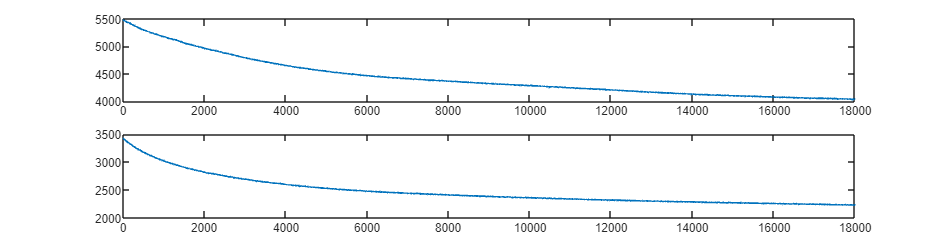

tj_raw=csvread('filter/33.8 mA RED, 27.1 mA IR/180_detik_IR_RED_tanpajari.csv');
IR_tj_raw = tj_raw(:, 1);
RED_tj_raw = tj_raw(:, 2);
f = figure;  
f.Position = [10 10 1550 400]; 
subplot(2,1,1); plot(IR_tj_raw);
subplot(2,1,2); plot(RED_tj_raw);

## Jari Moren

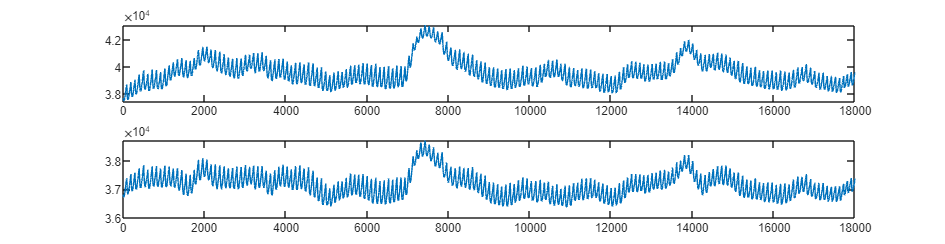

mn_raw=csvread('filter/33.8 mA RED, 27.1 mA IR/180_detik_IR_RED_moren.csv');

IR_mn_raw = mn_raw(:, 1);
RED_mn_raw = mn_raw(:, 2);
f = figure;  
f.Position = [10 10 1550 400]; 
subplot(2,1,1); plot(IR_mn_raw);
subplot(2,1,2); plot(RED_mn_raw);

## Jari Kay

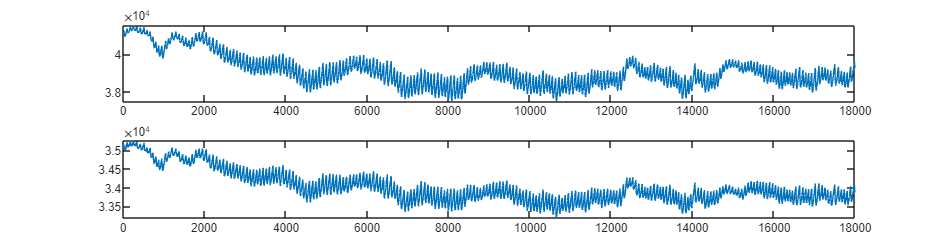

ky_raw=csvread('filter/33.8 mA RED, 27.1 mA IR/180_detik_IR_RED_kay.csv');
IR_ky_raw = ky_raw(:, 1);
RED_ky_raw = ky_raw(:, 2);
f = figure;  
f.Position = [10 10 1550 400]; 
subplot(2,1,1); plot(IR_ky_raw);
subplot(2,1,2); plot(RED_ky_raw);

IR_ky_raw_low = lowpass(IR_ky_raw,5,100);

# Spectral Analysis

fs = 100;           % 100 sps
n = 8192;
fn = (0:n-1)*(fs/n);

## Tanpa Jari

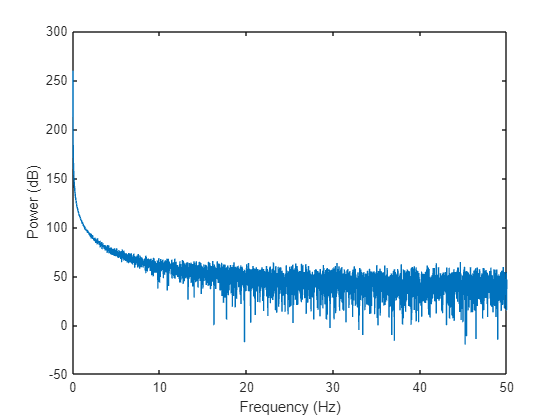

y_tj = fft(IR_tj_raw(1:8192).');
power_tj = 10*log(abs(y_tj).^2/n);      % power of the DTFS

f = figure;
plot(fn(1:8192/2),power_tj(1:8192/2))   % setengah fs
xlabel('Frequency (Hz)')
ylabel('Power (dB)')

## Jari Moren

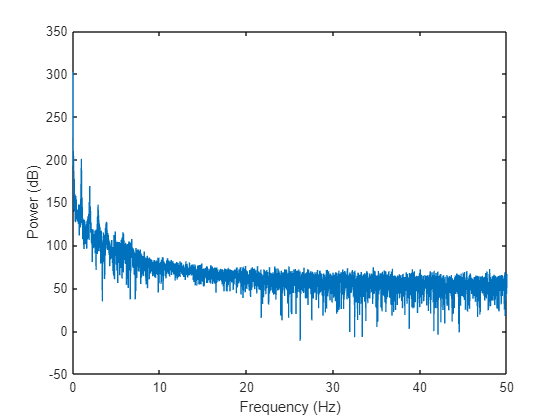

y_mn = fft(IR_mn_raw(1:8192).');
power_mn = 10*log(abs(y_mn).^2/n);      % power of the DTFS

f = figure;
plot(fn(1:8192/2),power_mn(1:8192/2))   % setengah fs
xlabel('Frequency (Hz)')
ylabel('Power (dB)')

## Jari Kay

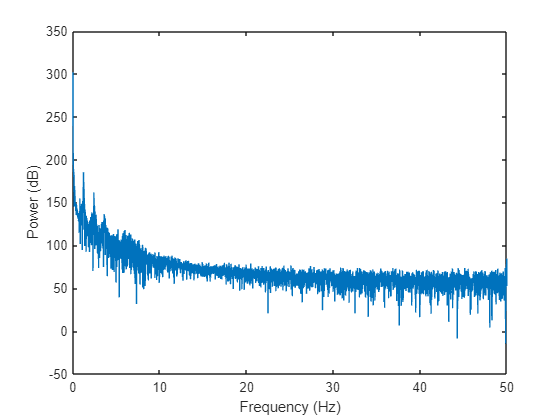

y_ky = fft(IR_ky_raw(1:8192).');
power_ky = 10*log(abs(y_ky).^2/n);      % power of the DTFS

f = figure;
plot(fn(1:8192/2),power_ky(1:8192/2))   % setengah fs
xlabel('Frequency (Hz)')
ylabel('Power (dB)')

# Test

## Matlab Documentation

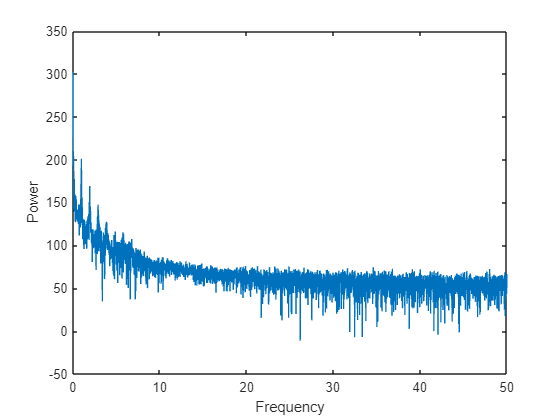

fs = 100;                                % sample frequency (Hz)
x = IR_mn_raw(1:8192).';
n = length(x);          % number of samples

y1 = fft(x);
f1 = (0:n-1)*(fs/n);     % frequency range
power1 = 10*log(abs(y1).^2/n);    % power of the DFT

f = figure;
plot(f1(1:8192/2),power1(1:8192/2))
xlabel('Frequency')
ylabel('Power')

## Matlab Forum

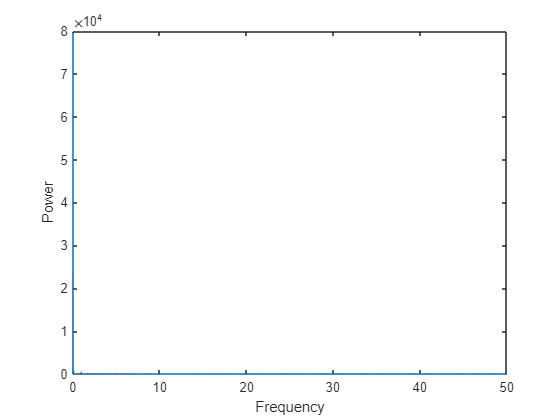

NFFT = 2^nextpow2(n); % Next power of 2 from length of y

y2 = fft(x,NFFT);
f2 = fs/2*linspace(0,1,NFFT/2+1);
power2 = 2*abs(y2(1:NFFT/2+1))/n;

f = figure;
% plot(f2(1:500),power2(1:500)) 
plot(f2,power2) 
xlabel('Frequency')
ylabel('Power')

# Signal Analyzer

## Sinyal Inframerah dan Merah Moren

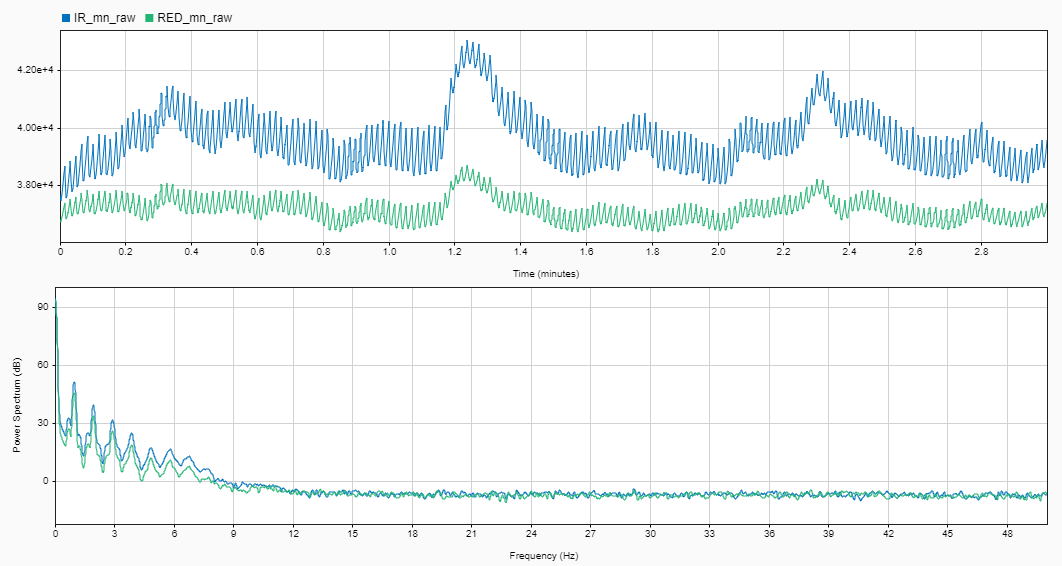

## Sinyal Inframerah Moren

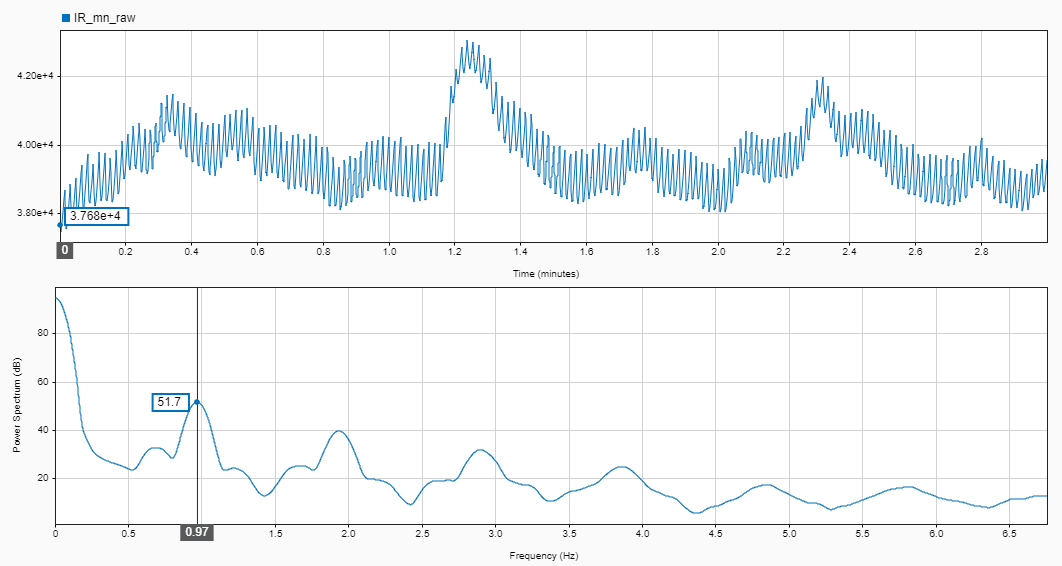

## Sinyal Inframerah Moren, Kay, dan Noise

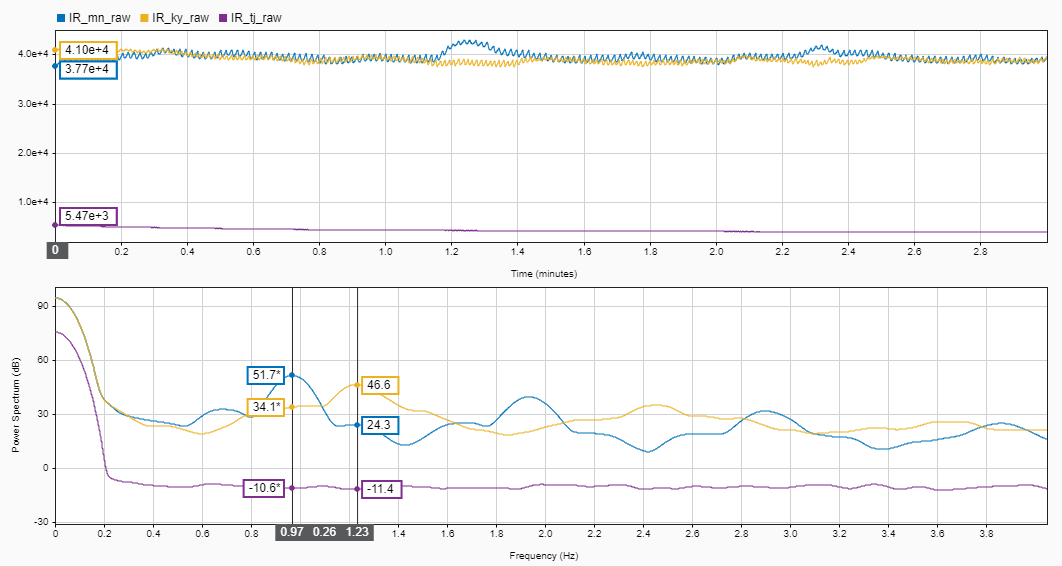

## Sinyal Noise

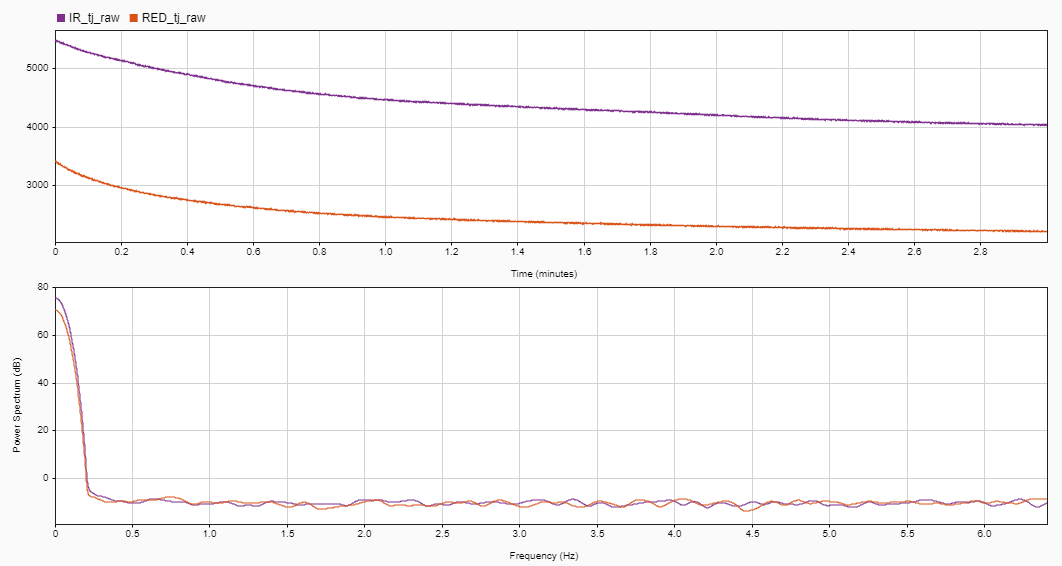

## Sinyal Inframerah dan Merah Moren dan Noise Pada 40 Hz

## 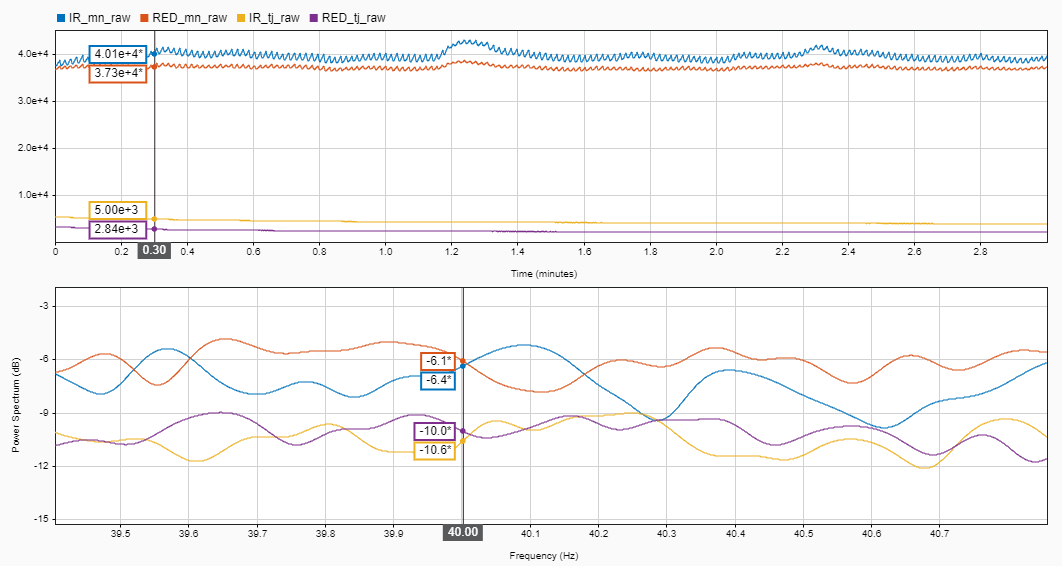

## Perbandingan Panjang Sampel

IR_mn_raw_8192 = IR_mn_raw(1:8192);
IR_mn_raw_16384 = IR_mn_raw(1:16384);

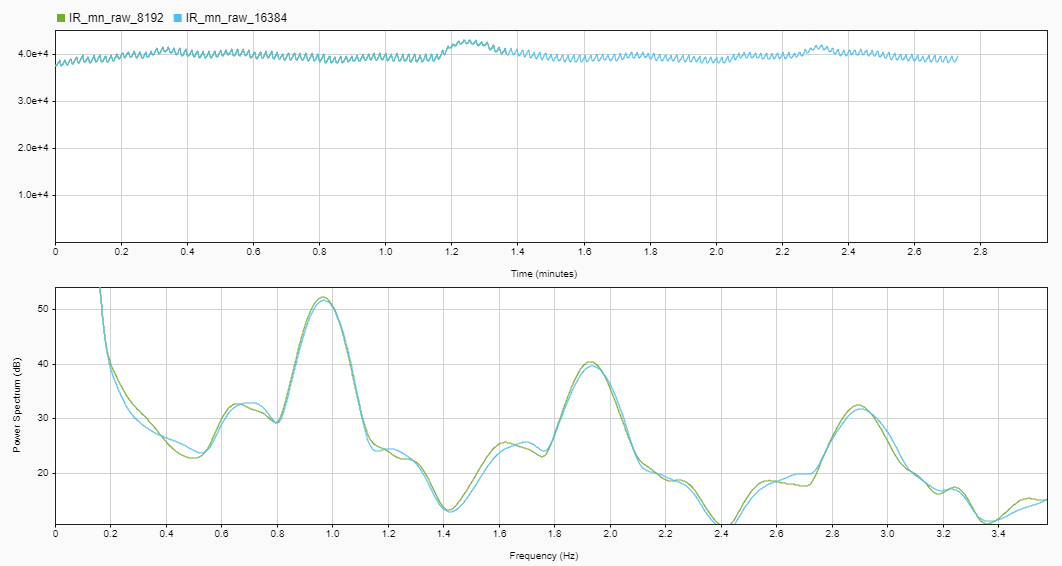

## Perbandingan Hasil Band Pass Filter Sinyal Inframerah Moren

% Fs = 1/mean(diff(tx)); % Average sample rate
% y = bandpass(x,[0.41667 4.16667],Fs,'Steepness',0.85,'StopbandAttenuation',60);

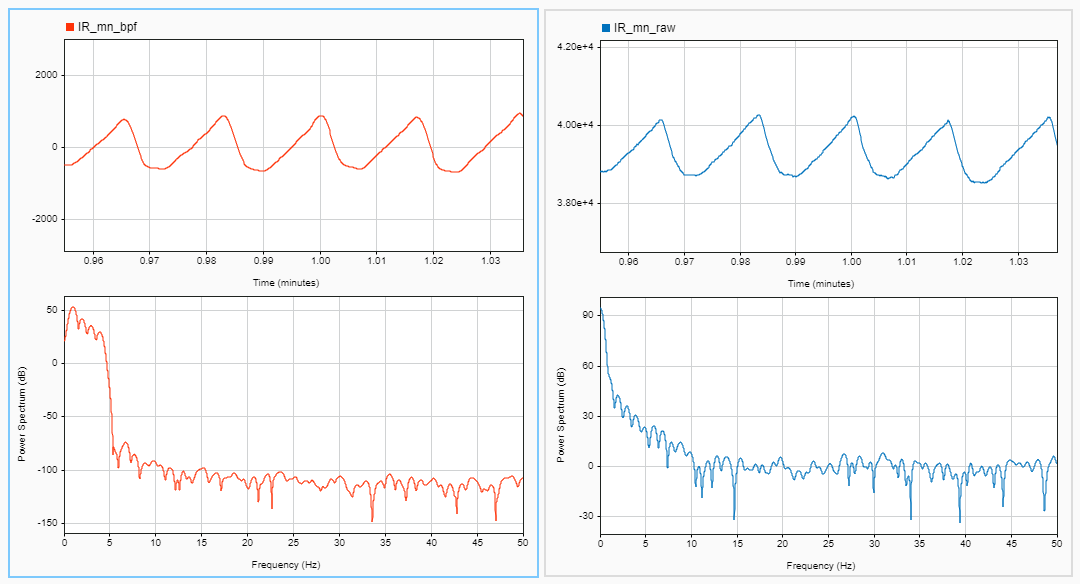

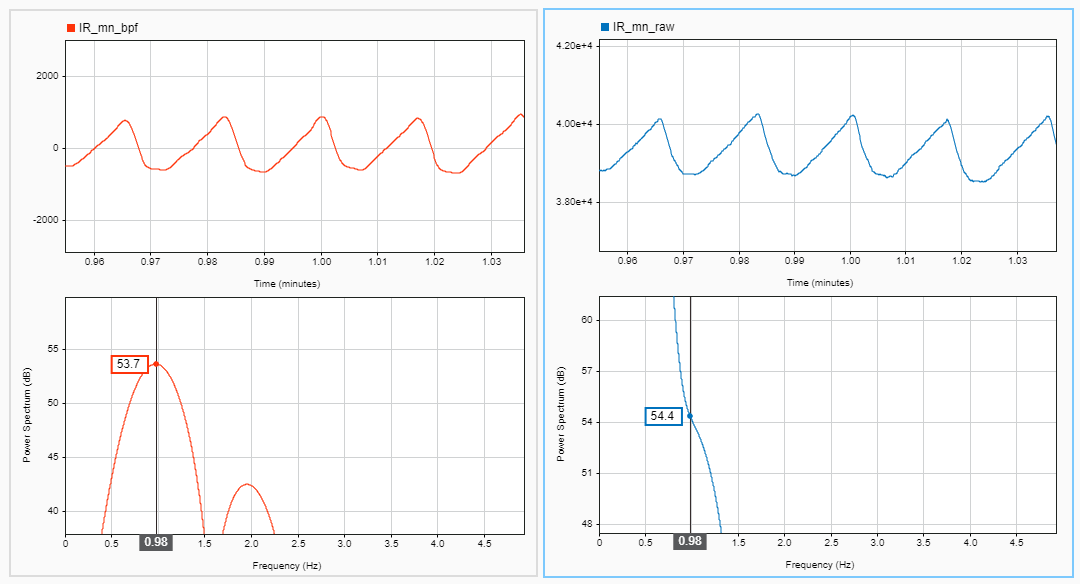

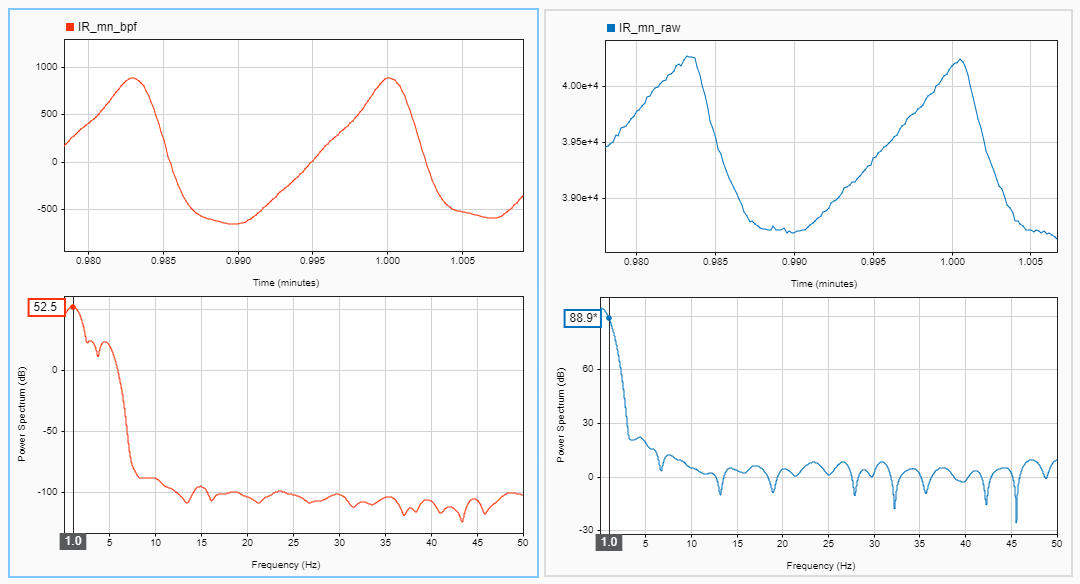

# Desain Filter FIR

## Low Pass Filter

% y(n) - 1.7821y(n-1) + 0.7882y(n-2) = x(n) - x(n-2)
b_lpf = [0.022103306919670853009085575990866345819 0.090845885923324792843303043810010422021 0.233609522704152222649653936059621628374 0.306882568905704256057020984371774829924 0.233609522704152222649653936059621628374 0.090845885923324792843303043810010422021 0.022103306919670853009085575990866345819];                % koefisien x
a_lpf = [1];   % koefisien y
yi_lpf = [];             % kondisi awal [y(-1) y(-2)]
zi_lpf = filtic(b_lpf,a_lpf,yi_lpf);    % kondisi awal untuk delay filter
yIR_lpf = filter(b_lpf,a_lpf,IR_mn_raw,zi_lpf); % menghitung y(n) untuk n>=0, n=0 ada di indeks MATLAB k=21

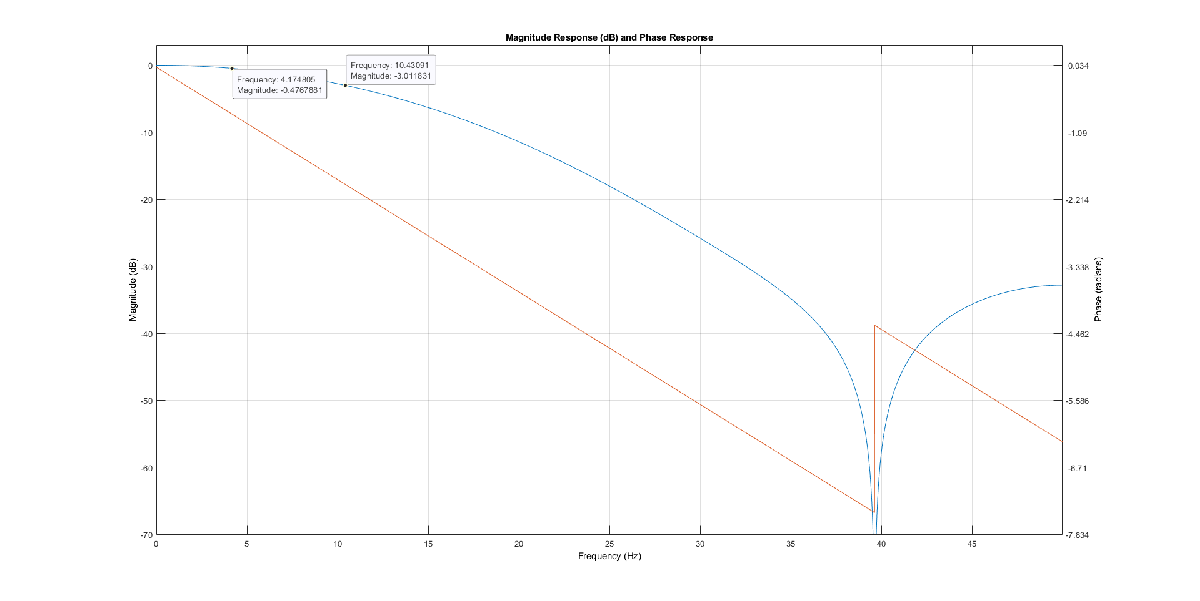

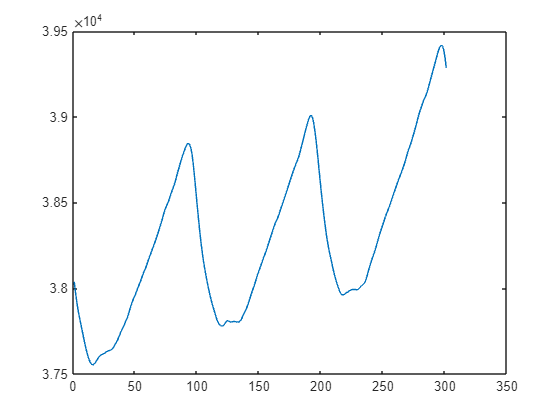

f = figure;
plot(yIR_lpf(100:400))

## High Pass Filter

b_hpf = [-0.000665543423242987200981468642879690378 -0.002580454651955923529860204013175462023 -0.006411713562822019332743117558948142687  0.991006395331781808621940399461891502142 -0.006411713562822019332743117558948142687 -0.002580454651955923529860204013175462023 -0.000665543423242987200981468642879690378];                % koefisien x
a_hpf = [1];   % koefisien y
yi_hpf = [];             % kondisi awal [y(-1) y(-2)]
zi_hpf = filtic(b_hpf,a_hpf,yIR_lpf);    % kondisi awal untuk delay filter
yIR_hpf = filter(b_hpf,a_hpf,yIR_lpf,zi_hpf); % menghitung y(n) untuk n>=0, n=0 ada di indeks MATLAB k=21

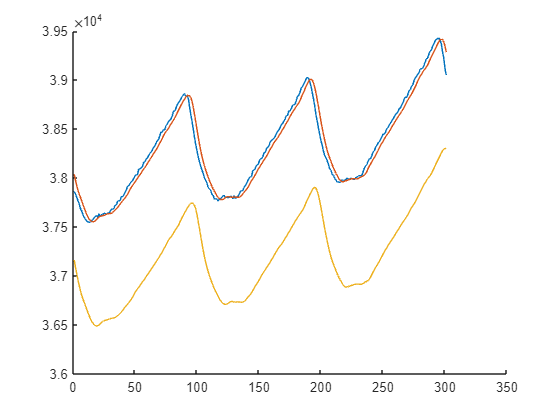

f = figure; hold on;

% plot(IR_mn_raw)
% plot(yIR)
% plot(yIR2)

plot(IR_mn_raw(100:400))
plot(yIR_lpf(100:400))
plot(yIR_hpf(100:400))

hold off;

# Desain Filter IIR Chebyshev II

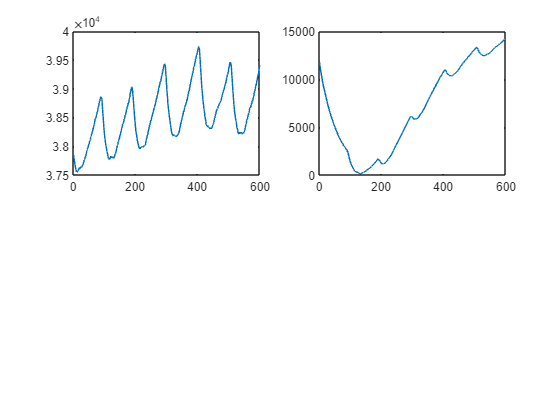

% y(n) - 1.7821y(n-1) + 0.7882y(n-2) = x(n) - x(n-2)
b_c = [1 -1.99997993436135779177220683777704834938 1];                % koefisien x
a_c = [1 -1.990994256806844386886723441421054303646 0.991057309168709377189543374697677791119];   % koefisien y
yi_c = [0 0];             % kondisi awal [y(-1) y(-2)]
zi_c = filtic(b_c,a_c,yi_c);    % kondisi awal untuk delay filter
yIR_c = filter(b_c,a_c,IR_mn_raw,zi_c); % menghitung y(n) untuk n>=0, n=0 ada di indeks MATLAB k=21

f = figure;

% plot(IR_mn_raw)
% plot(yIR)
% plot(yIR2)

subplot(2,2,1); plot(IR_mn_raw(100:700))
subplot(2,2,2); plot(yIR_c(100:700))

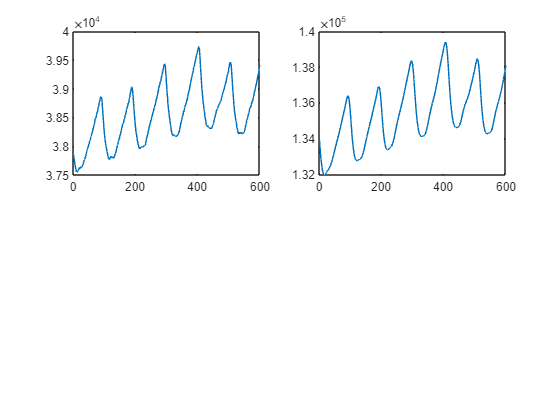

% y(n) - 1.7821y(n-1) + 0.7882y(n-2) = x(n) - x(n-2)
b_c2 = [1 -1.73275334939938163714145957783330231905 1];                % koefisien x
a_c2 = [1 -1.638864251542531569327820761827751994133 0.714935545843599529192147201683837920427];   % koefisien y
yi_c2 = [0 0];             % kondisi awal [y(-1) y(-2)]
zi_c2 = filtic(b_c2,a_c2,yi_c2);    % kondisi awal untuk delay filter
yIR_c2 = filter(b_c2,a_c2,IR_mn_raw,zi_c2); % menghitung y(n) untuk n>=0, n=0 ada di indeks MATLAB k=21

f = figure;

% plot(IR_mn_raw)
% plot(yIR)
% plot(yIR2)

subplot(2,2,1); plot(IR_mn_raw(100:700))
subplot(2,2,2); plot(yIR_c2(100:700))

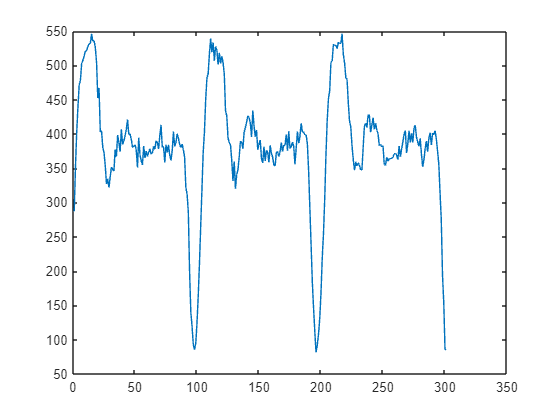

f = figure;
plot(yIR(100:400))

## 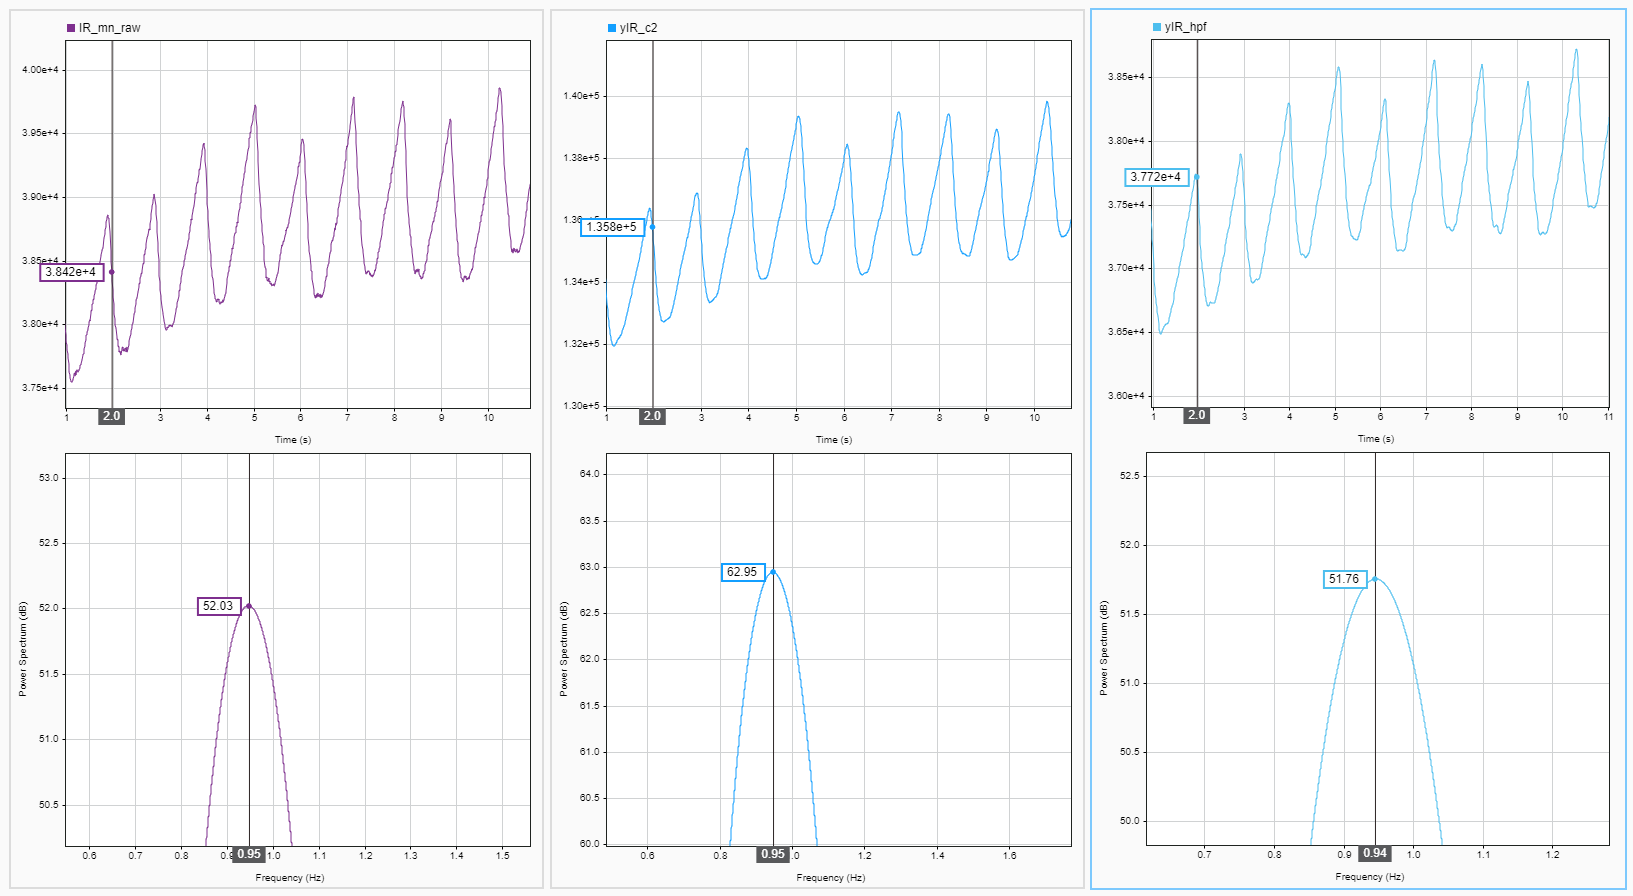

Array=csvread('moren_filter/68_detik_IR_RED_napasterus.csv');
IR = Array(:, 1);
RED = Array(:, 2);
f = figure;  
f.Position = [10 10 1550 400]; 
subplot(2,1,1); plot(IR);
subplot(2,1,2); plot(RED);
plot(RED)

% y(n) - 1.7821y(n-1) + 0.7882y(n-2) = x(n) - x(n-2)
b = [1 0 -1];                % koefisien x
a = [1 -1.7821 0.7882];   % koefisien y
yi = [0 0];             % kondisi awal [y(-1) y(-2)]
zi = filtic(b,a,yi);    % kondisi awal untuk delay filter
yIR = filter(b,a,IR,zi); % menghitung y(n) untuk n>=0, n=0 ada di indeks MATLAB k=21

f = figure;  
f.Position = [10 10 1550 400]; 
subplot(2,1,1); plot(IR(200:500));
subplot(2,1,2); plot(yIR(200:500));

yRED = filter(b,a,RED,zi); % menghitung y(n) untuk n>=0, n=0 ada di indeks MATLAB k=21

f = figure;  
f.Position = [10 10 1550 400]; 
subplot(2,1,1); plot(RED(200:500));
subplot(2,1,2); plot(yRED(200:500));

Array=csvread('\moren_filter\68_detik_IR_RED.csv');
IR = Array(:, 1);
RED = Array(:, 2);
f = figure;  
f.Position = [10 10 1550 400]; 
subplot(2,1,1); plot(IR);
subplot(2,1,2); plot(RED);
plot(RED)

IR_ky_raw_8192 = IR_ky_raw(1:8192);
RED_ky_raw_8192 = RED_ky_raw(1:8192);

RED_mn_raw_8192 = RED_mn_raw(1:8192);
IR_tj_raw_8192 = IR_tj_raw(1:8192);
RED_tj_raw_8192 = RED_tj_raw(1:8192);

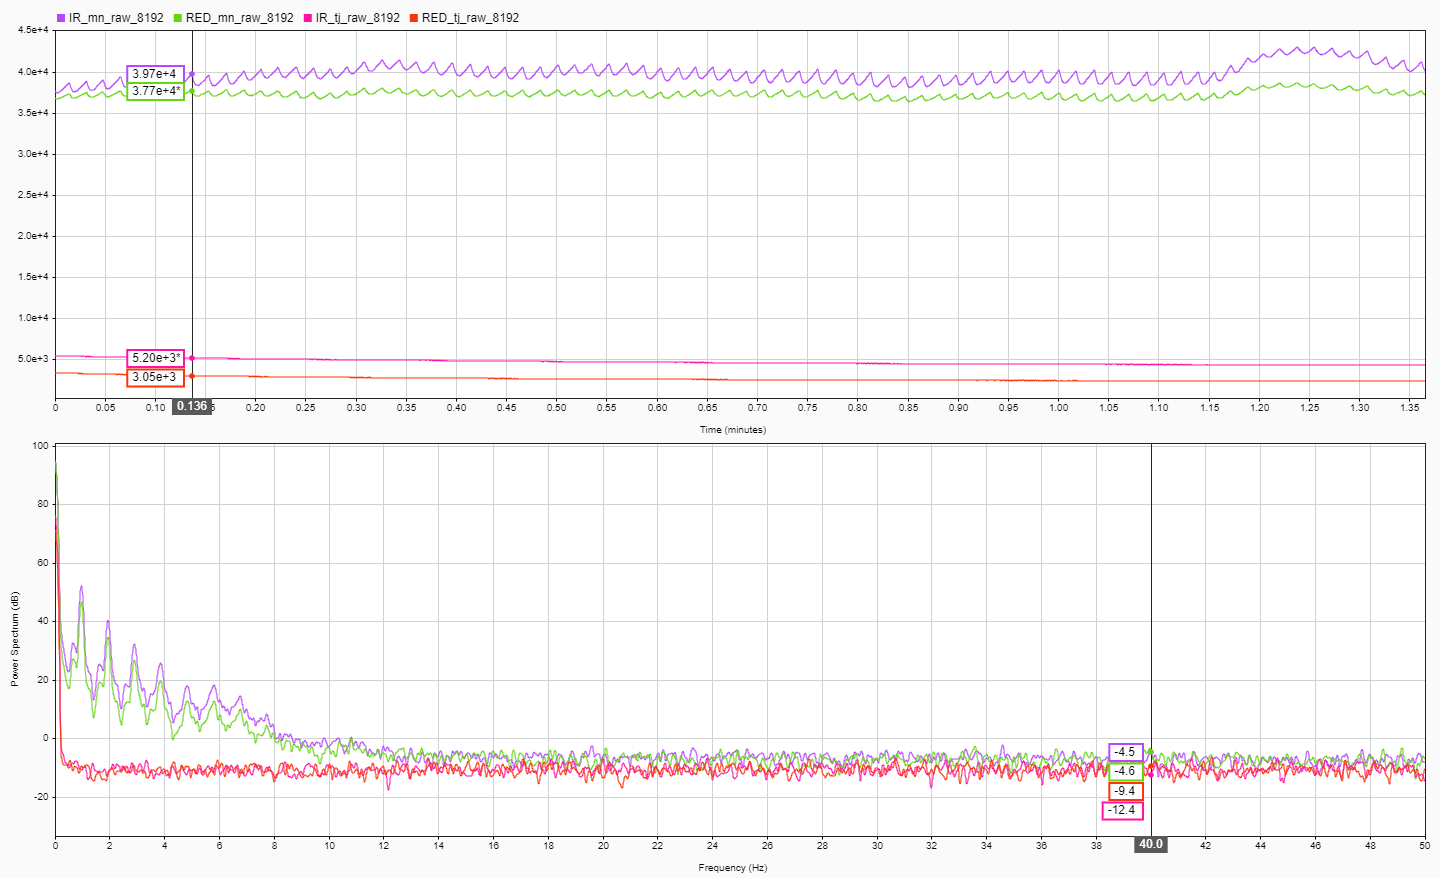

# TSRA PKK EL

## Pressure Sensor

clc
clear all
close all

pressure_file=csvread('tsra/data_pressure.csv');
pressure_data = pressure_file(:, 1);

% biasa 1400-2400
% tahan 10500-11500
% ngorok 15500-16500

biasa_data = pressure_data(1400:2400);
tahan_data = pressure_data(10500:11500);
ngorok_data = pressure_data(15500:16500);